# GReS - Quick Start Guide

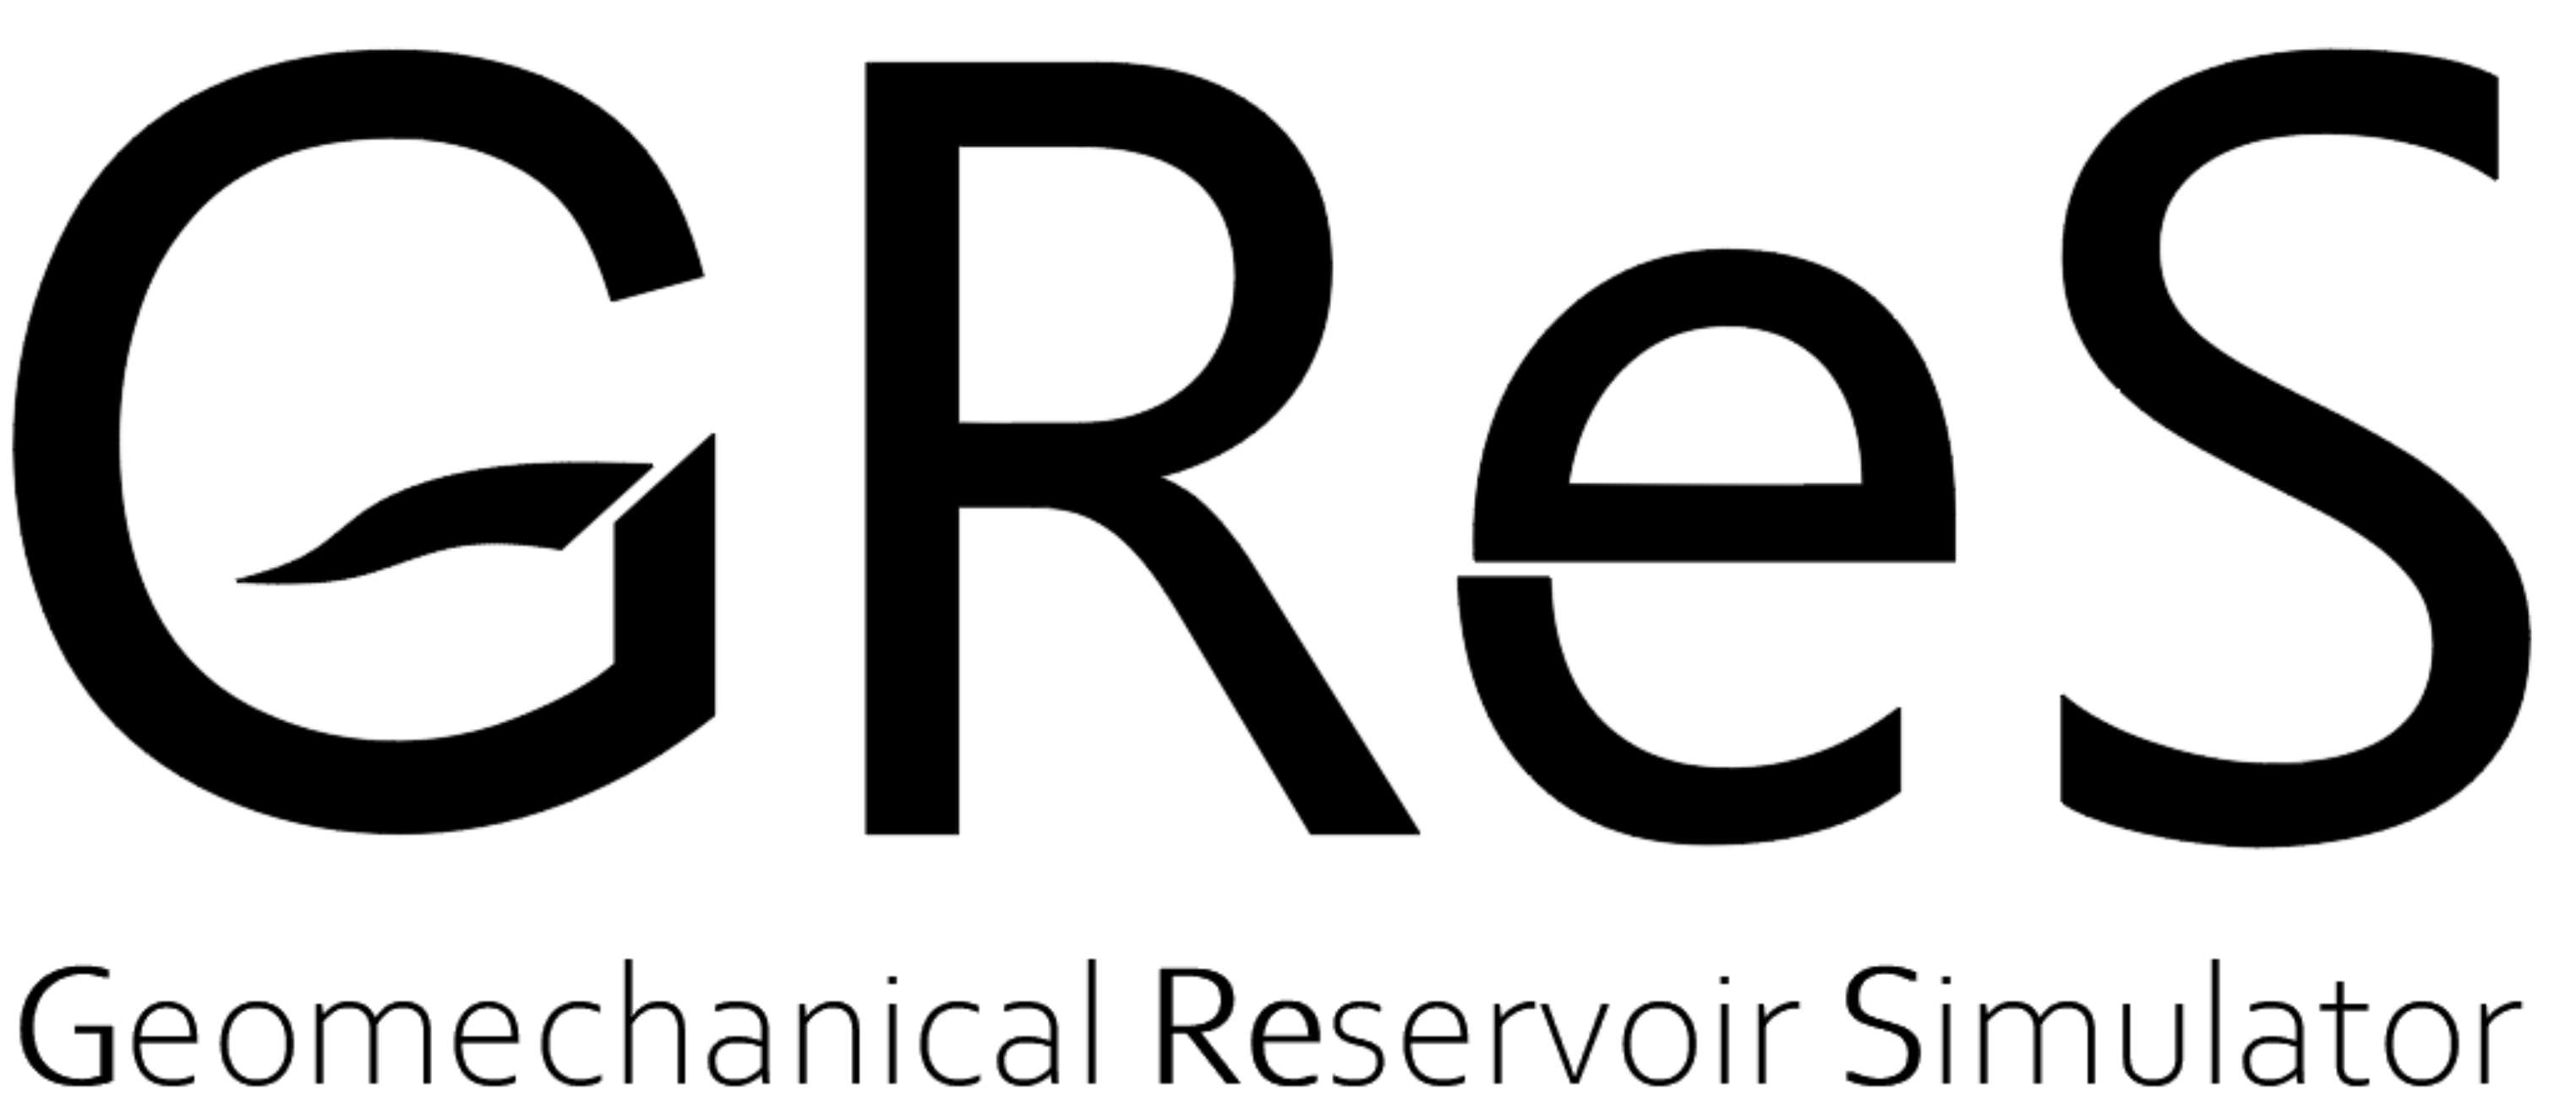

Welcome to GReS, the Geomechanical Reservoir Simulator developed at the University of Padova.

GReS is a robust simulator that puts a strong emphasis on geomechanics while also incorporating various other physics such as singlephase flow, multiphase flow and thermal dynamics.

Written in MATLAB, GReS offers maximum flexibility and has been designed to lower the entry barrier for new users, making it accessible to a wide range of researchers and professionals.

cd(fullfile(gres_root,'Tutorial'))

## Before starting

Before starting, you need to update the current Matlab search path. Move to the GReS base folder

cd('../')

 and run

initGReS

This function ensures that Matlab uses the correct path to the GReS subfolders.

initGReS also initializes a [logger](matlab:open('../Code/logger/Logger.m')), a global object that can be called from any location to log messages according to a specified verbosity,. By default, the verbosity is 1 when the logger is created. To inspect the verbosity, use command

gresLog().getVerbosity

while use the `gresLog().setVerbosity(N)` command to set it to N. 

gresLog().setVerbosity(2)
gresLog().getVerbosity

Now, we can exploit gresLog() to print something in the command window according to some minimum verbosity

gresLog().log(2,"Hello GReS!")

effectively print since the verbosity is smaller or equal to the current one.

Conversely

gresLog().log(3,"GReS will log nothing")

GReS implement several mex functions to achieve efficiency. [Mex functions](https://www.mathworks.com/help/matlab/call-mex-file-functions.html) are matlab interfaces to compiled C++ code. Make sure that the [mex](https://www.mathworks.com/help/matlab/ref/mex.html) command is configured to use a valid compiler. You can check this running

mex -setup C++

 To compile the code run

compileAll

## Tutorials

Some working examples are available in the `Tests` folder. Moreover, A series of interactive tutorials will guide you into understanding the main features of GReS. We recommend following these tutorials in the proposed order.

*First steps*:

- [Input Files](matlab:open('./inputFiles/input.mlx'))

- [Generating grids](matlab:open('./meshInput/meshIO.mlx'))

- [From the basics to advanced model: a step-by-step simulation](matlab:open('./stepBystepSimulation/stepBystep.m'))

*Documented Physics models*

- [Poroelasticity (Biot's equations)](matlab:open('./terzaghiPoroelasticity/terzaghi.mlx'))

- [Unsaturated Flow (Richard's equations)](matlab:open('./richardsUnsaturatedFlow/richards.mlx'))

*Simulation examples*

- [A simple, first example](matlab:open('../Tests/Flux_barrier/Main.m'))

- [Coupled simulation](matlab:open('../Tests/Mandel_Biot/Main.m'))

- [Multi-domain simulations](matlab:open('../Tests/Flow_nonConforming/Main.m'))

*Contributors guide (work in progress)*

- Github Workflow

- Adding a New PhysicsSolver